# BCI project procedure - Preprocessing (Without ICA)

**1) Rejection of bad EEG channels for each run and each subject**

For this first part, the bad EEG channels have been rejected for each run and each subject. First, it is important to select which are the subjects that are going to be used in this project among the fifteen healthy subjects that have participated in this study. On this occasion, the subjects are S1, S2, S3, S6, S7, S9, S11, S13.

It is interesting to mention that the data available for each subject consists of ten runs with 6 trials per run and the EEG signals were recorded from 61 channels covering frontal, central, parietal, and temporal areas. 

We have also chosen to show how long the calculations take, considering that the amount of data is not insignificant and thus, a good run time is desired.

subject_list= ["S1", "S2", "S3", "S6", "S7", "S9", "S11", "S13"];
addpath('functions')
waitfor(msgbox("In the next step, please select the path where eeglab is found", 'EEGLAB path selection'));
    eegpath=uigetdir;
    addpath(eegpath)
    waitfor(msgbox("Finally, please select your loc file", 'Loc file selection'));
    [locs,locpath]=uigetfile('*.loc', 'Pick a channel location file');
    locpath=strrep(locpath,'\','\\'); %for windows
    locs=append(locpath,locs);

**NOTES: **

**Make sure the folder containing your 'data' folder is added to path. **

**For further info, check each function file where the procedure will be explained in depth.**

**Please be patient. Run time with automated ICA rejection will take approximately 1 h on most computers.   **

## D1. Artifacted channels for each subject and run

Above, we chose our initial parameters. Now we will preprocess. The first function we call selects the bad channels for each run and saves them to a .mat file.

tstart=tic;
d1_bad_channels(subject_list,true,locs);

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\vctrf\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (164617) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165417) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165753) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165368) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165462) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167058) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167574) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168122) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165116) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165547) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (164617) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165417) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165753) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165368) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165462) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167058) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167574) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168122) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165116) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165547) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167997) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165498) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166607) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166656) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166435) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165332) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166763) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166307) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166976) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166573) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (164617) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165417) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165753) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165368) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165462) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167058) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167574) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168122) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165116) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165547) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (164617) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165417) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165753) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165368) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165462) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167058) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167574) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168122) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165116) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165547) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (164617) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165417) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165753) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165368) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165462) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167058) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167574) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168122) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165116) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165547) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165417) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165753) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165368) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165462) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167058) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167574) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168122) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165116) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165547) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166257) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168385) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166031) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168179) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167997) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165498) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166607) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166656) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166435) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165332) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166763) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

Elapsed time is 37 minutes and 48.832182 seconds


clear EEG ALLEEG CURRENTSET ALLCOM
tstart=tic;
d1_bad_channels(subject_list,false,locs);
tEnd = toc(tstart);
fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

Elapsed time is 2 minutes and 44.630557 seconds


A table has been created with the artifacted channels, the ones considered as bad channels, for each subject and run.

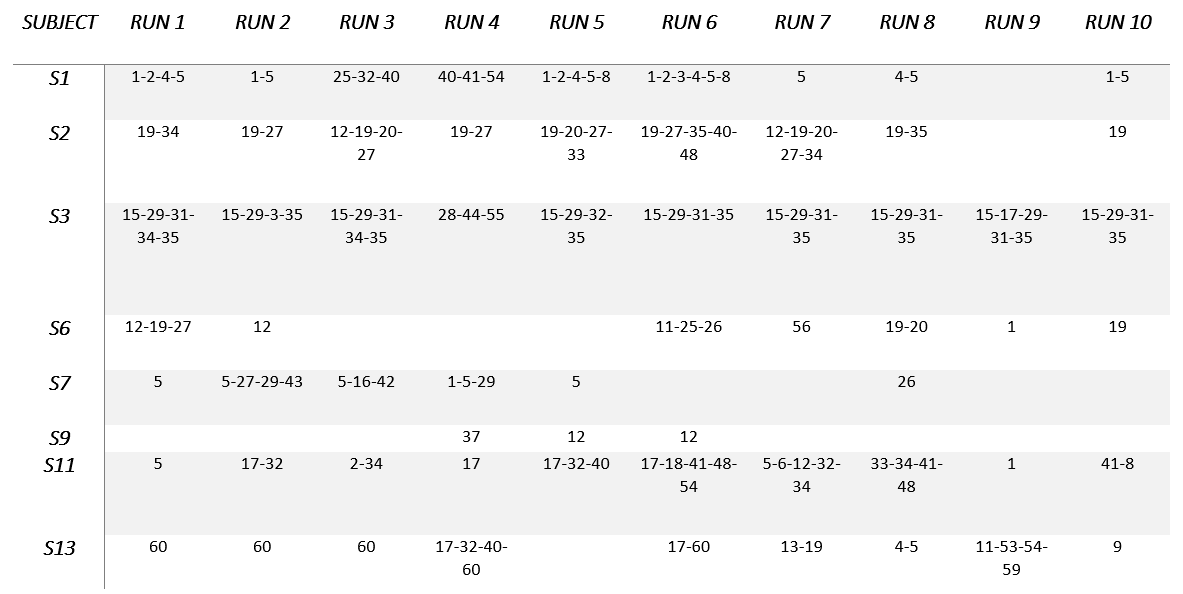

As can be observed in the table above, the channels for each run for each subject considered “bad channels” are shown. The cells with no “bad channel” are empty (-). It is important to mention that each channel has associated a label which determine the EEG electrode position. Some subjects may seem more interesting to take a second to mention on as for instance the subject number 9 which has almost no “bad channels” revealing that artifacts were not recorded. Also, subject number 3 shows some channels that are repeated in almost all the runs or a more heterogeneous distribution of bad channels during the different runs as subject 11 or subject 13. 

This time, the channels that were not eliminated for any run or subject were channels 7, 10, 14, 15, 21, 22, 23, 24, 30, 36, 38, 39, 45, 46, 47, 49, 50, 51, 52, 57, 58, and 61. 

In the table above, the bad channels resulting from the signal obtained when removing components with ICA are shown. 

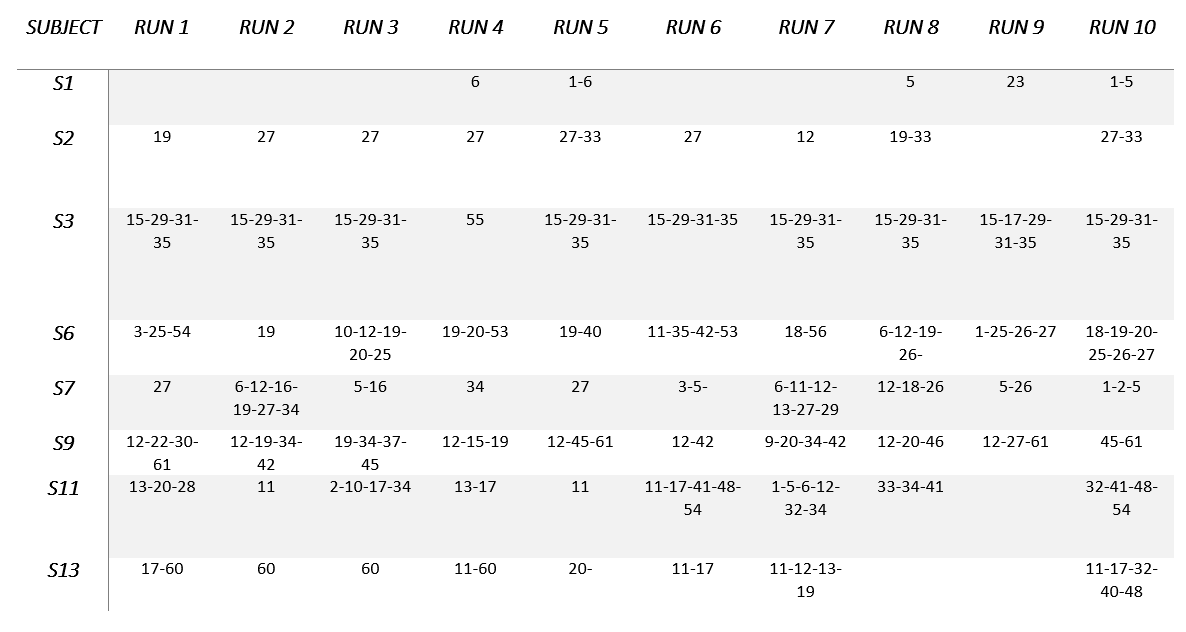

It can be interesting to mention that there are some channels that have never been considered "bad channels" for any run and subject, which, more precisely, are channels *4, 7, 8, 14, 21, 24, 36, 38, 39, 43, 44, 47, 49, 50, 51, 52, 57, 58, and 59*. 

**2) Rejection of bad trials for each movement and subject**

Once the bad channels have been selected, we run the second function to find the bad trials. It takes the movement code as an argument, so we run it for each movement. In this case, the movement classes are:

- Flexion (1536)

- Open hand (1541)

Below, the different runs for the bad trials, with the different arguments, are coded. The variations calculated have been done with and without ICA and with and without automatic movement detection, in all of the possible permutations, thus yielding four different solutions for each movement type.

%returns the matrix, now with bad trials marked too
tstart=tic;
d2_bad_trials(subject_list,1536,true,true)

Calculating bad trials for Elbow flexion
Elapsed time is 0.211384 seconds.
Elapsed time is 31.083431 seconds.
Elapsed time is 32.526035 seconds.
Elapsed time is 32.552019 seconds.
Elapsed time is 63.760239 seconds.
Elapsed time is 65.277384 seconds.
Elapsed time is 65.294989 seconds.
Elapsed time is 96.476575 seconds.
Elapsed time is 97.768353 seconds.
Elapsed time is 97.782607 seconds.
Elapsed time is 128.941256 seconds.
Elapsed time is 130.378444 seconds.
Elapsed time is 130.392309 seconds.
Elapsed time is 162.035321 seconds.
Elapsed time is 163.525557 seconds.
Elapsed time is 163.541986 seconds.
Elapsed time is 195.299712 seconds.
Elapsed time is 196.777551 seconds.
Elapsed time is 196.791199 seconds.
Elapsed time is 227.977463 seconds.
Elapsed time is 229.503589 seconds.
Elapsed time is 229.518361 seconds.
Elapsed time is 260.874805 seconds.
Elapsed time is 262.340662 seconds.
Elapsed time is 262.353908 seconds.
Elapsed time is 293.570709 seconds.
Elapsed time is 295.027241 seconds

tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

Elapsed time is 68 minutes and 10.195209 seconds


tstart=tic;
d2_bad_trials(subject_list,1536,false,true)

Calculating bad trials for Elbow flexion
Elapsed time is 1.715007 seconds.
Elapsed time is 1.724806 seconds.
Elapsed time is 2.830968 seconds.
Elapsed time is 2.832286 seconds.
Elapsed time is 3.984390 seconds.
Elapsed time is 3.985945 seconds.
Elapsed time is 5.068936 seconds.
Elapsed time is 5.071160 seconds.
Elapsed time is 6.248752 seconds.
Elapsed time is 6.250457 seconds.
Elapsed time is 7.344994 seconds.
Elapsed time is 7.346524 seconds.
Elapsed time is 8.497058 seconds.
Elapsed time is 8.498470 seconds.
Elapsed time is 9.616904 seconds.
Elapsed time is 9.619690 seconds.
Elapsed time is 10.652387 seconds.
Elapsed time is 10.654156 seconds.
Elapsed time is 11.768679 seconds.
Elapsed time is 11.770234 seconds.
Elapsed time is 12.880494 seconds.
Elapsed time is 12.882267 seconds.
Elapsed time is 14.049809 seconds.
Elapsed time is 14.053095 seconds.
Elapsed time is 15.232828 seconds.
Elapsed time is 15.234889 seconds.
Elapsed time is 16.332038 seconds.
Elapsed time is 16.333908 seco

tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

Elapsed time is 2 minutes and 40.373889 seconds



tstart=tic

tstart = uint64
1815463458867

d2_bad_trials(subject_list,1536,true,false)

Calculating bad trials for Elbow flexion
Elapsed time is 0.177602 seconds.
Elapsed time is 36.952292 seconds.
Elapsed time is 38.410763 seconds.
Elapsed time is 38.432139 seconds.
Elapsed time is 70.288804 seconds.
Elapsed time is 71.715140 seconds.
Elapsed time is 71.728423 seconds.
Elapsed time is 103.473744 seconds.
Elapsed time is 104.761719 seconds.
Elapsed time is 104.776594 seconds.
Elapsed time is 136.477716 seconds.
Elapsed time is 137.900988 seconds.
Elapsed time is 137.915779 seconds.
Elapsed time is 169.999100 seconds.
Elapsed time is 171.430696 seconds.
Elapsed time is 171.445297 seconds.
Elapsed time is 203.076462 seconds.
Elapsed time is 204.558685 seconds.
Elapsed time is 204.576915 seconds.
Elapsed time is 235.957972 seconds.
Elapsed time is 237.423730 seconds.
Elapsed time is 237.438667 seconds.
Elapsed time is 268.864824 seconds.
Elapsed time is 270.336518 seconds.
Elapsed time is 270.357698 seconds.
Elapsed time is 301.741389 seconds.
Elapsed time is 303.198737 seco

tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

Elapsed time is 105 minutes and 38.728963 seconds


tstart=tic;
d2_bad_trials(subject_list,1536,false,false)

Calculating bad trials for Elbow flexion
Elapsed time is 1.203008 seconds.
Elapsed time is 1.204790 seconds.
Elapsed time is 2.172812 seconds.
Elapsed time is 2.174323 seconds.
Elapsed time is 3.112638 seconds.
Elapsed time is 3.114014 seconds.
Elapsed time is 4.176074 seconds.
Elapsed time is 4.178382 seconds.
Elapsed time is 5.280497 seconds.
Elapsed time is 5.281705 seconds.
Elapsed time is 6.325021 seconds.
Elapsed time is 6.326485 seconds.
Elapsed time is 7.377549 seconds.
Elapsed time is 7.378948 seconds.
Elapsed time is 8.445142 seconds.
Elapsed time is 8.446487 seconds.
Elapsed time is 9.505401 seconds.
Elapsed time is 9.506734 seconds.
Elapsed time is 10.556437 seconds.
Elapsed time is 10.558615 seconds.
Elapsed time is 11.632010 seconds.
Elapsed time is 11.634362 seconds.
Elapsed time is 12.828022 seconds.
Elapsed time is 12.829990 seconds.
Elapsed time is 13.936480 seconds.
Elapsed time is 13.939032 seconds.
Elapsed time is 15.020343 seconds.
Elapsed time is 15.022027 second

tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

Elapsed time is 1 minutes and 57.108781 seconds



tstart=tic;
d2_bad_trials(subject_list,1541,true,true)

Calculating bad trials for Elbow flexion
Elapsed time is 0.140180 seconds.
Elapsed time is 36.795713 seconds.
Elapsed time is 38.258755 seconds.
Elapsed time is 38.275199 seconds.
Elapsed time is 69.967274 seconds.
Elapsed time is 71.402114 seconds.
Elapsed time is 71.415633 seconds.
Elapsed time is 102.705923 seconds.
Elapsed time is 103.992738 seconds.
Elapsed time is 104.006876 seconds.
Elapsed time is 135.265518 seconds.
Elapsed time is 136.675786 seconds.
Elapsed time is 136.689425 seconds.
Elapsed time is 167.688650 seconds.
Elapsed time is 169.112765 seconds.
Elapsed time is 169.129104 seconds.
Elapsed time is 200.002030 seconds.
Elapsed time is 201.454043 seconds.
Elapsed time is 201.467789 seconds.
Elapsed time is 232.317644 seconds.
Elapsed time is 233.771437 seconds.
Elapsed time is 233.785046 seconds.
Elapsed time is 264.893937 seconds.
Elapsed time is 266.350502 seconds.
Elapsed time is 266.365547 seconds.
Elapsed time is 297.539502 seconds.
Elapsed time is 298.992496 seco

tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

Elapsed time is 192 minutes and 26.824923 seconds


tstart=tic;
d2_bad_trials(subject_list,1541,false,true)

Calculating bad trials for Elbow flexion
Elapsed time is 2.422574 seconds.
Elapsed time is 2.425327 seconds.
Elapsed time is 4.143122 seconds.
Elapsed time is 4.145806 seconds.
Elapsed time is 5.527051 seconds.
Elapsed time is 5.529774 seconds.
Elapsed time is 7.054943 seconds.
Elapsed time is 7.057915 seconds.
Elapsed time is 8.547477 seconds.
Elapsed time is 8.549096 seconds.
Elapsed time is 9.943737 seconds.
Elapsed time is 9.946034 seconds.
Elapsed time is 11.412027 seconds.
Elapsed time is 11.413813 seconds.
Elapsed time is 12.782257 seconds.
Elapsed time is 12.783841 seconds.
Elapsed time is 14.275498 seconds.
Elapsed time is 14.278494 seconds.
Elapsed time is 15.922801 seconds.
Elapsed time is 15.925300 seconds.
Elapsed time is 17.404750 seconds.
Elapsed time is 17.406691 seconds.
Elapsed time is 19.125356 seconds.
Elapsed time is 19.128108 seconds.
Elapsed time is 20.722286 seconds.
Elapsed time is 20.724314 seconds.
Elapsed time is 22.149565 seconds.
Elapsed time is 22.151449 

tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

Elapsed time is 4 minutes and 0.151269 seconds



tstart=tic

tstart = uint64
1997892147501

d2_bad_trials(subject_list,1541,true,false)

Calculating bad trials for Elbow flexion
Elapsed time is 0.640035 seconds.
Elapsed time is 59.407710 seconds.
Elapsed time is 62.101956 seconds.
Elapsed time is 62.211556 seconds.
Elapsed time is 106.397758 seconds.
Elapsed time is 108.476740 seconds.
Elapsed time is 108.496249 seconds.
Elapsed time is 151.394702 seconds.
Elapsed time is 153.224245 seconds.
Elapsed time is 153.245464 seconds.
Elapsed time is 196.305204 seconds.
Elapsed time is 198.208192 seconds.
Elapsed time is 198.229169 seconds.
Elapsed time is 241.429270 seconds.
Elapsed time is 243.436238 seconds.
Elapsed time is 243.455507 seconds.
Elapsed time is 287.147844 seconds.
Elapsed time is 289.184324 seconds.
Elapsed time is 289.201316 seconds.
Elapsed time is 749.641218 seconds.
Elapsed time is 751.476408 seconds.
Elapsed time is 751.497789 seconds.
Elapsed time is 782.422197 seconds.
Elapsed time is 783.842635 seconds.
Elapsed time is 783.854829 seconds.
Elapsed time is 814.734101 seconds.
Elapsed time is 816.218565 s

tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

Elapsed time is 73 minutes and 56.795504 seconds


tstart=tic;
d2_bad_trials(subject_list,1541,false,false)

Calculating bad trials for Elbow flexion
Elapsed time is 1.731963 seconds.
Elapsed time is 1.733202 seconds.
Elapsed time is 2.705590 seconds.
Elapsed time is 2.707766 seconds.
Elapsed time is 3.619107 seconds.
Elapsed time is 3.620385 seconds.
Elapsed time is 4.593795 seconds.
Elapsed time is 4.595565 seconds.
Elapsed time is 5.627867 seconds.
Elapsed time is 5.629189 seconds.
Elapsed time is 6.626502 seconds.
Elapsed time is 6.628022 seconds.
Elapsed time is 7.611011 seconds.
Elapsed time is 7.612262 seconds.
Elapsed time is 8.613374 seconds.
Elapsed time is 8.614772 seconds.
Elapsed time is 9.612633 seconds.
Elapsed time is 9.614152 seconds.
Elapsed time is 10.607847 seconds.
Elapsed time is 10.609497 seconds.
Elapsed time is 11.609566 seconds.
Elapsed time is 11.610913 seconds.
Elapsed time is 12.792262 seconds.
Elapsed time is 12.793596 seconds.
Elapsed time is 13.901313 seconds.
Elapsed time is 13.904642 seconds.
Elapsed time is 15.006706 seconds.
Elapsed time is 15.007945 second

tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

Elapsed time is 2 minutes and 6.210959 seconds


We have also chosen to show how long the calculations take, considering that the amount of data is not insignificant and thus, a good run time is desired.

## D2. Percentage of good (artifact-free) trials for each subject and movement class

- **Without ICA and without automatic movement detection**

Now we will want to display the data. If the variables are not loaded, we will load them from the file created in the previous step.

if exist("bad_trials_1536",'var')==0
    bad_trials_1536=load("bad_trials_1536.mat","matrix_detrend");
    bad_trials_1536=bad_trials_1536.matrix_detrend;
end
if exist("bad_trials_1541",'var')==0
    bad_trials_1541=load("bad_trials_1541.mat","matrix_detrend");
    bad_trials_1541=bad_trials_1541.matrix_detrend;
end

Next, we create a table with the percentage of good trials for all channels. Considering we saved the bad trials and runs as NaNs, the following form creates and displays a table in Matlab's table format. On this occasion, the results in the table below are considering all channels. 

%create a table of good trial percentage per user/movement
T=[];
for subject=1:length(bad_trials_1536(1,1,1,:))
        T(subject,1)=nnz(~isnan(bad_trials_1536(:,:,:,subject)))/numel(bad_trials_1536(:,:,:,subject));
        T(subject,2)=nnz(~isnan(bad_trials_1541(:,:,:,subject)))/numel(bad_trials_1541(:,:,:,subject));

end
T=round(T,4)*100;
T=array2table(T,"RowNames",subject_list,"VariableNames",["Elbow Flexion", "Hand Opening"]);
disp(T)

           Elbow Flexion    Hand Opening
           _____________    ____________

    S1         91.56           92.54    
    S2         84.02           85.85    
    S3         89.62           91.45    
    S6         88.63           88.63    
    S7         93.33           93.52    
    S9         91.42           91.83    
    S11        89.23           89.15    
    S13        93.06           82.05    



In the table above, it can be seen the percentage of artifact-free trials for each subject for all the channels depending on the movement class. On one hand, regarding the elbow flexion, the subject 2 is the one presenting a lower rate of artifact-free trials while the subject 7 present the better result. On the other hand, as refers to the hand opening, the subject 13 presents a lower percentage while the subject 9 presents the higher percentage of artifact-free trials. 

- **With reduction of contamination by ICA**

if exist("bad_trials_1536_with_ica",'var')==0
    bad_trials_1536_with_ica=load("bad_trials_1536_with_ica.mat","matrix_detrend");
    bad_trials_1536_with_ica=bad_trials_1536_with_ica.matrix_detrend;
end
if exist("bad_trials_1541_with_ica",'var')==0
    bad_trials_1541_with_ica=load("bad_trials_1541_with_ica.mat","matrix_detrend");
    bad_trials_1541_with_ica=bad_trials_1541_with_ica.matrix_detrend;
end

%create a table of good trial percentage per user/movement
T2=[];
for subject=1:length(bad_trials_1536_with_ica(1,1,1,:))
        T2(subject,1)=nnz(~isnan(bad_trials_1536_with_ica(:,:,:,subject)))/numel(bad_trials_1536_with_ica(:,:,:,subject));
        T2(subject,2)=nnz(~isnan(bad_trials_1541_with_ica(:,:,:,subject)))/numel(bad_trials_1541_with_ica(:,:,:,subject));

end
T2=round(T2,4)*100;
T2=array2table(T2,"RowNames",subject_list,"VariableNames",["Elbow Flexion", "Hand Opening"]);

Error using array2table (line 81)
The RowNames property must contain one name for each row in the table.

disp(T2)

- **With automatic detection of movement onset**

if exist("bad_trials_1536_with_auto",'var')==0
    bad_trials_1536_with_auto=load("bad_trials_1536_with_auto.mat","matrix_detrend");
    bad_trials_1536_with_auto=bad_trials_1536_with_auto.matrix_detrend;
end
if exist("bad_trials_1541_with_auto",'var')==0
    bad_trials_1541_with_auto=load("bad_trials_1541_with_auto.mat","matrix_detrend");
    bad_trials_1541_with_auto=bad_trials_1541_with_auto.matrix_detrend;
end

%create a table of good trial percentage per user/movement
T3=[];
for subject=1:length(bad_trials_1536_with_auto(1,1,1,:))
        T3(subject,1)=nnz(~isnan(bad_trials_1536_with_auto(:,:,:,subject)))/numel(bad_trials_1536_with_auto(:,:,:,subject));
        T3(subject,2)=nnz(~isnan(bad_trials_1541_with_auto(:,:,:,subject)))/numel(bad_trials_1541_with_auto(:,:,:,subject));

end
T3=round(T3,4)*100;
T3=array2table(T3,"RowNames",subject_list,"VariableNames",["Elbow Flexion", "Hand Opening"]);
disp(T3)

- **With automatic detection of movement onset and with reduction of contamination by ICA**

if exist("bad_trials_1536_with_ica_with_auto",'var')==0
    bad_trials_1536_with_ica_with_auto=load("bad_trials_1536_with_ica_with_auto.mat","matrix_detrend");
    bad_trials_1536_with_ica_with_auto=bad_trials_1536_with_ica_with_auto.matrix_detrend;
end
if exist("bad_trials_1541_with_ica_with_auto",'var')==0
    bad_trials_1541_with_ica_with_auto=load("bad_trials_1541_with_ica_with_auto.mat","matrix_detrend");
    bad_trials_1541_with_ica_with_auto=bad_trials_1541_with_ica_with_auto.matrix_detrend;
end

%create a table of good trial percentage per user/movement
T4=[];
for subject=1:length(bad_trials_1536_with_ica_with_auto(1,1,1,:))
        T4(subject,1)=nnz(~isnan(bad_trials_1536_with_ica_with_auto(:,:,:,subject)))/numel(bad_trials_1536_with_ica_with_auto(:,:,:,subject));
        T4(subject,2)=nnz(~isnan(bad_trials_1541_with_ica_with_auto(:,:,:,subject)))/numel(bad_trials_1541_with_ica_with_auto(:,:,:,subject));

end
T4=round(T4,4)*100;
T4=array2table(T4,"RowNames",subject_list,"VariableNames",["Elbow Flexion", "Hand Opening"]);
disp(T4)

Then we create a table for **Cz (channel 30)** only, in order to compare our results with the example given.

- **Without ICA and without automatic movement detection**

T30=[];
for subject=1:length(bad_trials_1536(1,1,1,:))
        T30(subject,1)=nnz(~isnan(bad_trials_1536(30,:,:,subject)))/numel(bad_trials_1536(30,:,:,subject));
        T30(subject,2)=nnz(~isnan(bad_trials_1541(30,:,:,subject)))/numel(bad_trials_1541(30,:,:,subject));

end

Unrecognized function or variable 'bad_trials_1536'.

T30=round(T30,4)*100;
T30=array2table(T30,"RowNames",subject_list,"VariableNames",["Elbow Flexion", "Hand Opening"]);
disp(T30)

Although, for hand opening, subject 1's results are the same, subject 2 has a slightly lower good trial rate in the given data. This could be due to the filtering and processing methodology, and was therefore not considered to be an issue.

- **With reduction of contamination by ICA**

T31=[];
for subject=1:length(bad_trials_1536_with_ica(1,1,1,:))
        T31(subject,1)=nnz(~isnan(bad_trials_1536_with_ica(30,:,:,subject)))/numel(bad_trials_1536_with_ica(30,:,:,subject));
        T31(subject,2)=nnz(~isnan(bad_trials_1541_with_ica(30,:,:,subject)))/numel(bad_trials_1541_with_ica(30,:,:,subject));

end
T31=round(T31,4)*100;
T31=array2table(T31,"RowNames",subject_list,"VariableNames",["Elbow Flexion", "Hand Opening"]);
disp(T31)

- **With automatic detection of movement onset**

T32=[];
for subject=1:length(bad_trials_1536_with_auto(1,1,1,:))
        T32(subject,1)=nnz(~isnan(bad_trials_1536_with_auto(30,:,:,subject)))/numel(bad_trials_1536_with_auto(30,:,:,subject));
        T32(subject,2)=nnz(~isnan(bad_trials_1541_with_auto(30,:,:,subject)))/numel(bad_trials_1541_with_auto(30,:,:,subject));

end
T32=round(T32,4)*100;
T32=array2table(T32,"RowNames",subject_list,"VariableNames",["Elbow Flexion", "Hand Opening"]);
disp(T32)

- **With automatic detection of movement onset and with reduction of contamination by ICA**

T33=[];
for subject=1:length(bad_trials_1536_with_ica_with_auto(1,1,1,:))
        T33(subject,1)=nnz(~isnan(bad_trials_1536_with_ica_with_auto(30,:,:,subject)))/numel(bad_trials_1536_with_ica_with_auto(30,:,:,subject));
        T33(subject,2)=nnz(~isnan(bad_trials_1541_with_ica_with_auto(30,:,:,subject)))/numel(bad_trials_1541_with_ica_with_auto(30,:,:,subject));

end
T33=round(T33,4)*100;
T33=array2table(T33,"RowNames",subject_list,"VariableNames",["Elbow Flexion", "Hand Opening"]);
disp(T33)

## D3. Plots

In this section, the average (considering only the good trials) for channel Cz for each subject and class movement has been represented. Moreover, the grand-mean average (average of all subjects) of trials for Cz and each movement class.

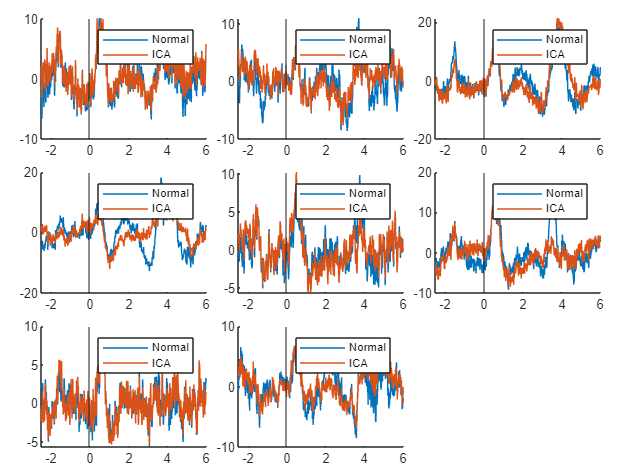

ho_30=squeeze(mean(bad_trials_1541(30,:,:,:),3,'omitnan'));
ef_30=squeeze(mean(bad_trials_1536(30,:,:,:),3,'omitnan'));

ica1536=load("bad_trials_1536_with_ica.mat");
ica1541=load("bad_trials_1541_with_ica.mat");

ho_30_ica=squeeze(mean(ica1541.matrix_detrend(30,:,:,:),3,'omitnan'));
ef_30_ica=squeeze(mean(ica1536.matrix_detrend(30,:,:,:),3,'omitnan'));
fm=512;
t=-0.5+1/fm:1/fm:(4352-0.5*512)/fm;
figure(6)
tiledlayout('flow','TileSpacing','compact','Padding','compact')
for i=1:8

    nexttile
    hold on
    plot(t,ho_30(:,i))
    plot(t,ho_30_ica(:,i))  
    xline(0)
    xline(2)
    xlim([-0.5 8])
    hold off
    legend('Normal','ICA')
end

figure
tiledlayout('flow','TileSpacing','compact','Padding','compact')
for i=1:8

    nexttile
    hold on
    plot(t,ef_30(:,i))
    plot(t,ef_30_ica(:,i))
    xline(0)
    xline(2)
    xlim([-0.5 8])
    hold off
    legend('Normal','ICA')
end

ica1536=load("bad_trials_1536_with_ica_with_auto.mat");
ica1541=load("bad_trials_1541_with_ica_with_auto.mat");

ho_30_ica_auto=squeeze(mean(ica1541.matrix_detrend(30,:,:,:),3,'omitnan'));
ef_30_ica_auto=squeeze(mean(ica1536.matrix_detrend(30,:,:,:),3,'omitnan'));

ica1536=load("bad_trials_1536_with_auto.mat");
ica1541=load("bad_trials_1541_with_auto.mat");

ho_30_auto=squeeze(mean(ica1541.matrix_detrend(30,:,:,:),3,'omitnan'));
ef_30_auto=squeeze(mean(ica1536.matrix_detrend(30,:,:,:),3,'omitnan'));

gm_average_30_ho=mean(ho_30,2);
gm_30_ica_ho=mean(ho_30_ica,2);
gm_30_ho_auto=mean(ho_30_auto,2);
gm_30_ica_auto_ho=mean(ho_30_ica_auto,2);

figure
plot(t,gm_average_30_ho)
hold on
plot(t,gm_30_ica_ho)
plot(t,gm_30_ho_auto)
plot(t,gm_30_ica_auto_ho)
xline(-2)
xline(0)
legend('Normal','ICA','Auto detect','ICA + Auto')

hold off

gm_average_30_ef=mean(ef_30,2);
gm_30_ica_ef=mean(ef_30_ica,2);
gm_30_ef_auto=mean(ef_30_auto,2);
gm_30_ica_auto_ef=mean(ef_30_ica_auto,2);

figure
plot(t,gm_average_30_ef)
hold on
plot(t,gm_30_ica_ef)
plot(t,gm_30_ef_auto)
plot(t,gm_30_ica_auto_ef)
xline(-2)
xline(0)
legend('Normal','ICA','Auto detect','ICA + Auto')

hold off